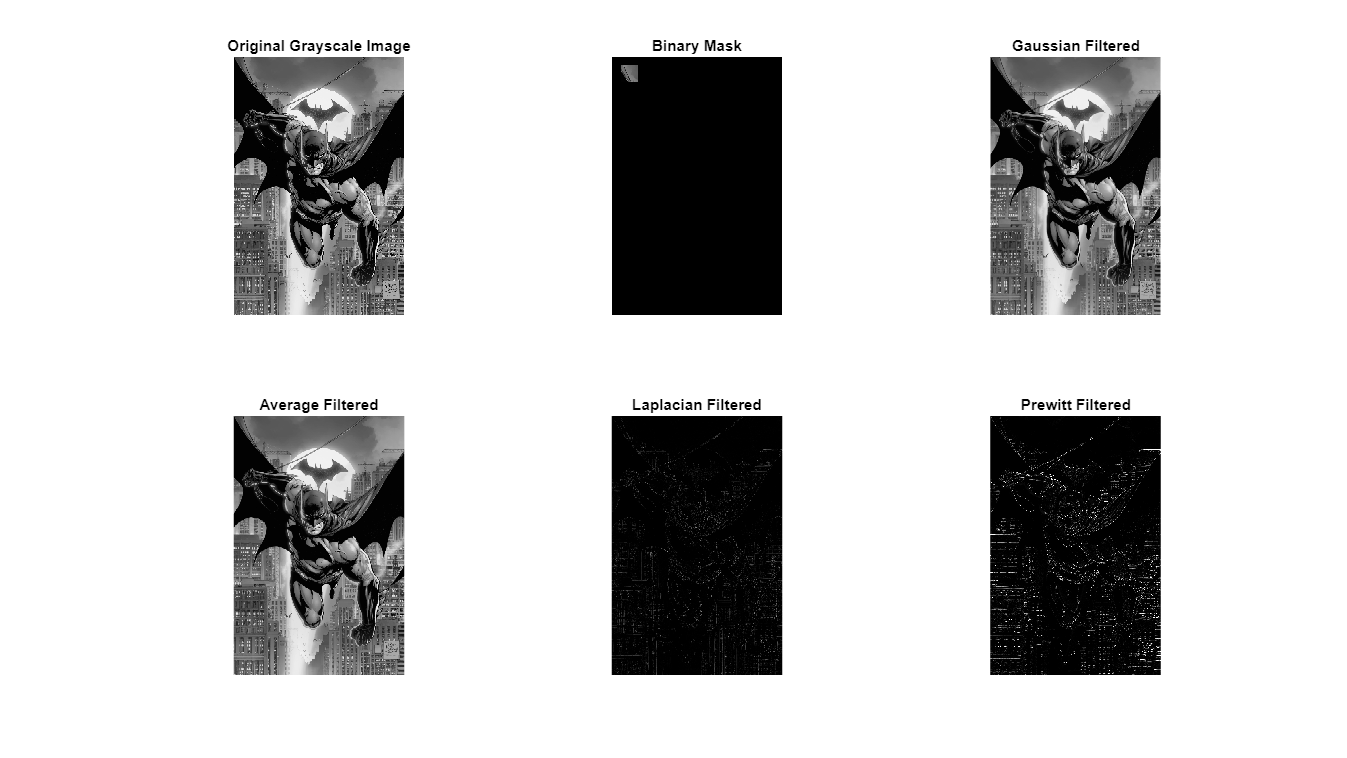

% Load the image
originalImg = imread('Bat.jpg');
if size(originalImg, 3) == 3
    grayImg = rgb2gray(originalImg);
else
    grayImg = originalImg;
end

% Display original grayscale image
figure;
subplot(2,3,1);
imshow(grayImg);
title('Original Grayscale Image');

% Create a binary mask manually for this example
% Assume an arbitrary ROI around the central part of the image
mask = false(size(grayImg));
mask(100:300, 100:300) = true;

% Apply the mask and show it
maskedImg = grayImg;
maskedImg(~mask) = 0;
subplot(2,3,2);
imshow(maskedImg);
title('Binary Mask');

% Apply Gaussian Filter
gaussianFiltered = imgaussfilt(grayImg, 2);
subplot(2,3,3);
imshow(gaussianFiltered);
title('Gaussian Filtered');

% Apply Average Filter
averageFiltered = imfilter(grayImg, fspecial('average', [5 5]));
subplot(2,3,4);
imshow(averageFiltered);
title('Average Filtered');

% Apply Laplacian Filter
laplacianFiltered = imfilter(grayImg, fspecial('laplacian'));
subplot(2,3,5);
imshow(laplacianFiltered, []);
title('Laplacian Filtered');

% Apply Prewitt Filter
prewittFiltered = imfilter(grayImg, fspecial('prewitt'));
subplot(2,3,6);
imshow(prewittFiltered);
title('Prewitt Filtered');

% Display all images
set(gcf, 'Position', get(0, 'Screensize')); % Make it fullscreen for better visibility